# **PDE工具箱求解波动方程演示**

**问题1：考虑一个二维的波动问题，定解问题如下。**


$$\begin{array}{l}
u_{\textrm{tt}} -\Delta u=0\\
{u\left|\right.}_{t=0} =0\\
{u_t \left|\right.}_{t=0} =3*\sin \left(\pi x\right)*\sin \left(\pi y\right)\\
{u\left|\right.}_{x=0} =0,{u\left|\right.}_{x=1} =0\\
{u_y \left|\right.}_{y=0} =0,{u_y \left|\right.}_{y=1} =0
\end{array}$$


**        该定解问题可以看作在一个边长为1的正方形谐振腔内，电磁场的纵向电场分量随时间做简谐振动的情况。**

**        首先，利用分离变量法求解得到的解析解为：**


$$u=\frac{3}{\sqrt{2}\pi }$$

$$\sin \left(\pi x\right)*\sin \left(\pi y\right)*\sin \left(\sqrt{2}\pi t\right)$$


**        绘制在t=1,2,3,4四个时刻的图像，如图**

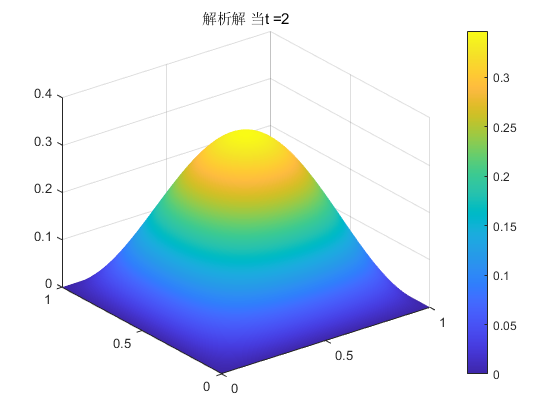

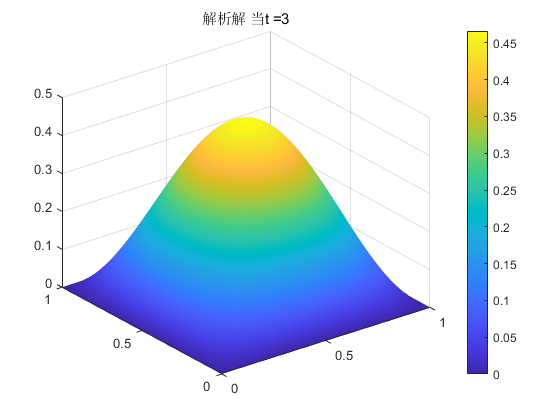

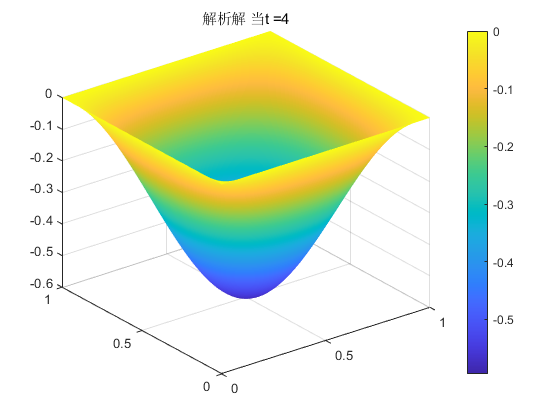

clc
clear
x=linspace(0,1,100);                     	%x取从0到1区间的100个点
y=linspace(0,1,100);                     	%y取从0到1区间的100个点
[X,Y]=meshgrid(x,y);                    	%绘制网格，并将格点坐标赋于X和Y
t=[1 2 3 4];
for  i=1:4                             	%循环四次，绘制四个时刻电场值。
    u=3/(sqrt(2)*pi)*sin(pi*X).*sin(pi*Y)*sin(sqrt(2)*pi*t(i));  %计算电势值
    figure(i)
    surf(X,Y,u);                            	%绘制曲面图 
    shading interp;                          	%曲面色彩做插值
    colorbar;                               %绘制带色阶的颜色条
    title(strcat('解析解 当t = ', num2str(i)));
    set(gcf,'Visible','on');   	    %强制图片弹出显示
end

**        接下来，打开PDETool图形界面，对工具栏进行相关设置从而得到该问题的数值解，并绘制图形。具体的步骤如下。**

** （1）在MATLAB界面下方输入”pdetool“（注意大小写），即可进入到PDETool界面；**

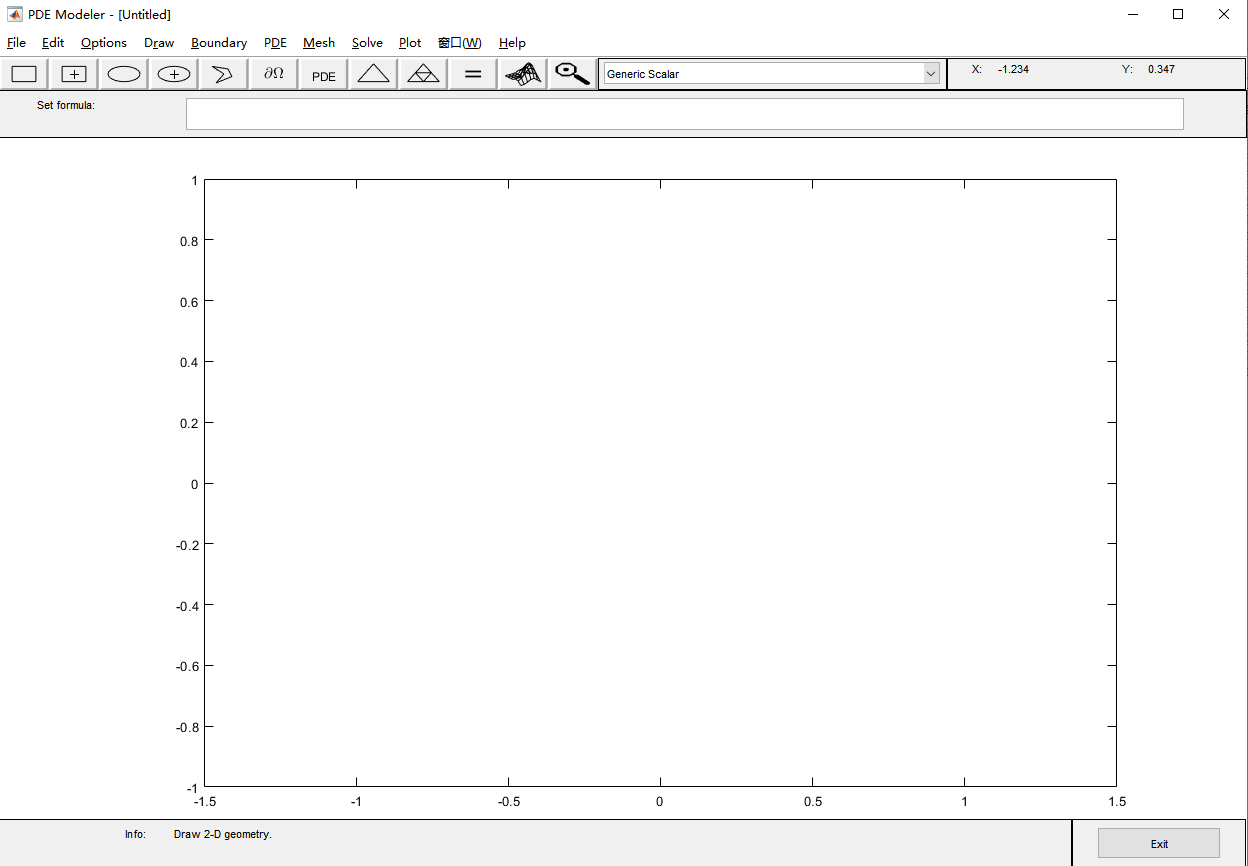

**       （2）绘制边长为1的正方形，双击正方形可设置具体参数坐标；**

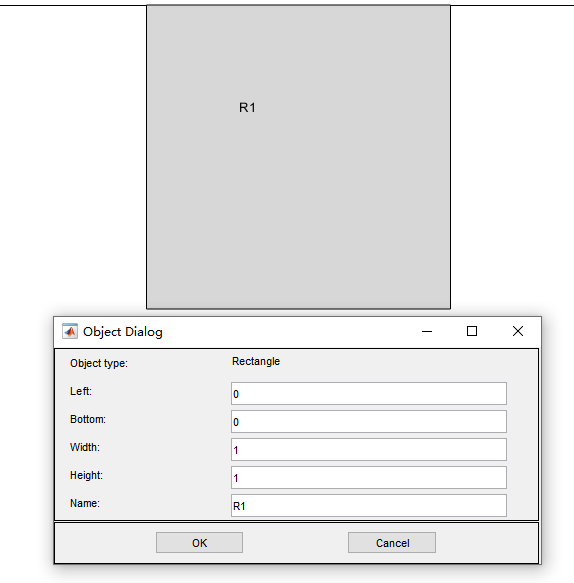

**       （3）单击"Boundary-Boundary Mode"，双击正方形区域的边界即可设置，如下图所示；**

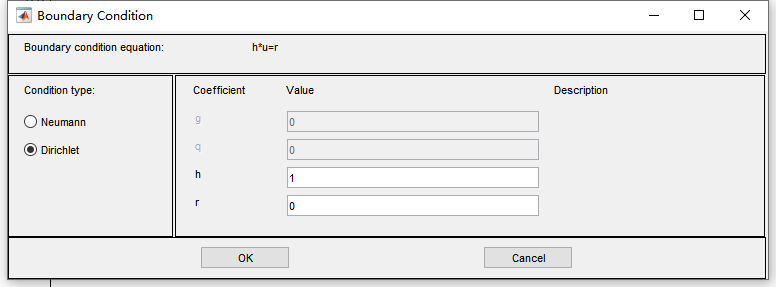

**       （4）点击“PDE-PDE Specification”选择双曲线型方程，并做如下设置；**

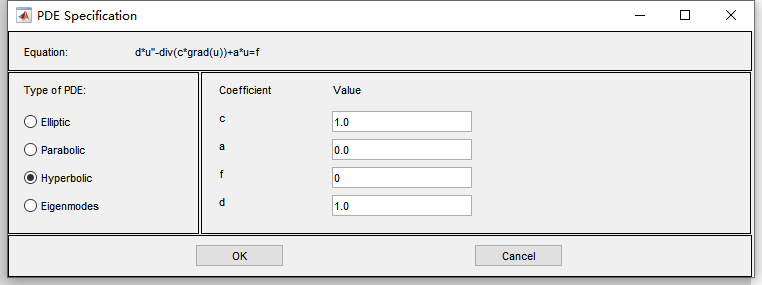

**       （5）点击“Solve-Parameters”设置初始条件；**

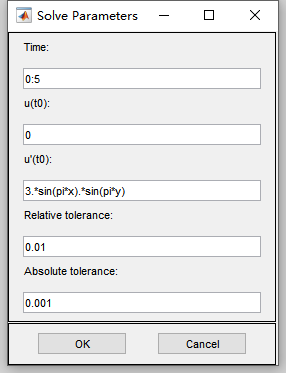

**       （6）点击“Mesh-Refine mesh”进行网格划分；**

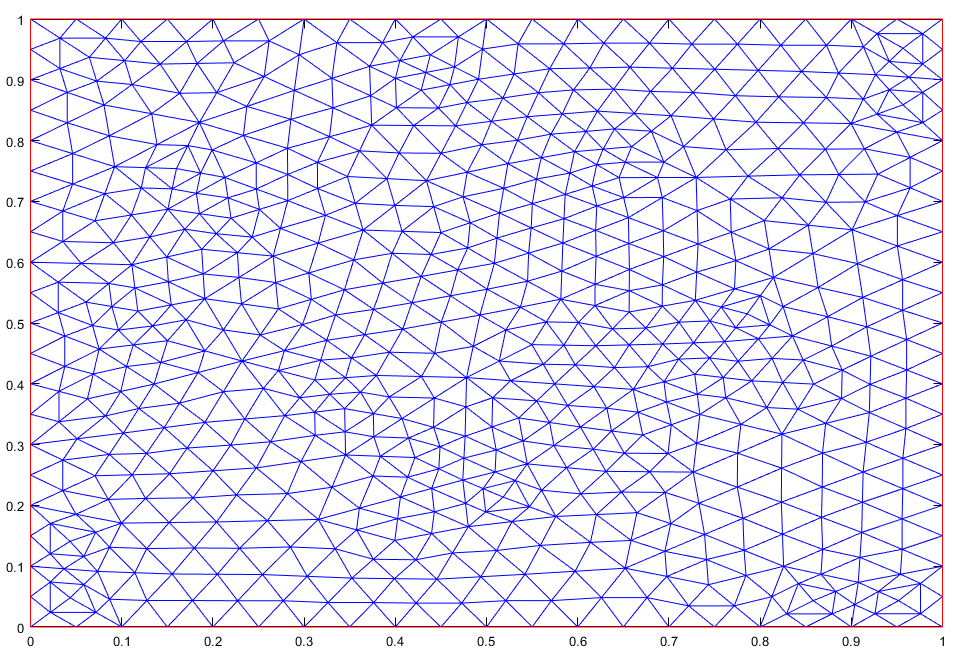

**       （7）点击“Solve-Solve PDE”进行计算，并点击“Plot-Parameters”设置1,2,3,4四个时刻的高度图；**

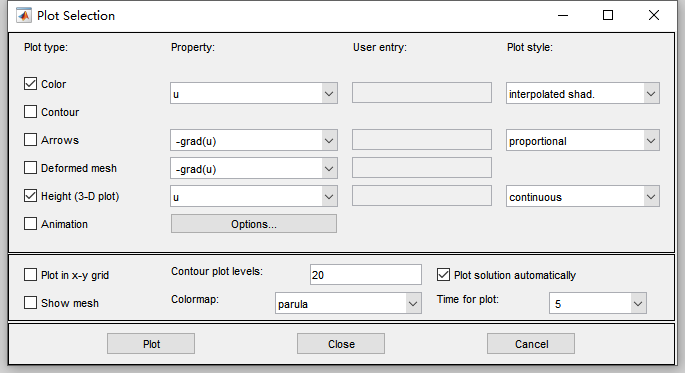

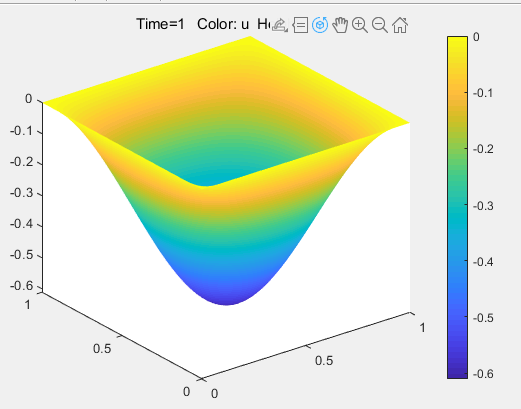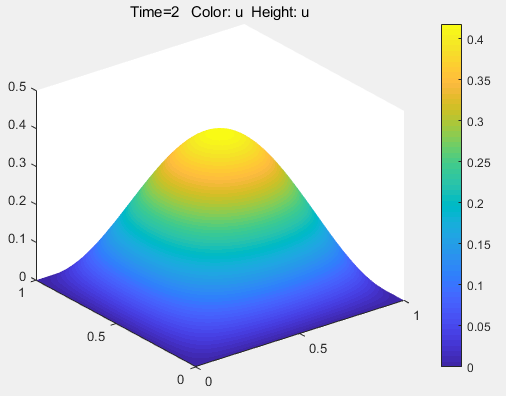

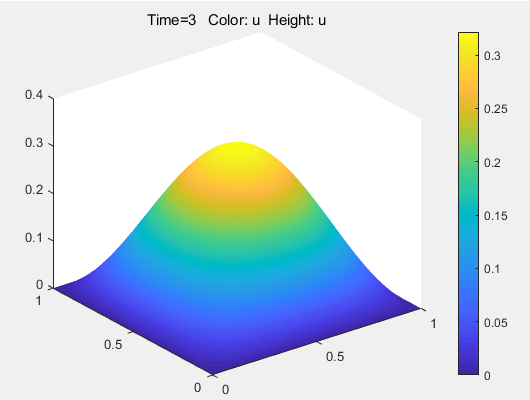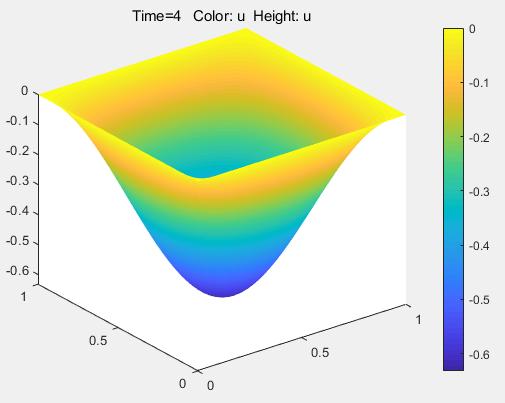

**       在具体的计算中，设置时间为0~5s，步长为0.01s。当数值计算结束后，单击绘图按钮，设置需显示的时刻的值。经过对比可以验证，解析解与数值仿真解的场分布是相同的。**

t =2;
exit = true;%是否运行后退出
figure(5)
pdemodel(t,exit);

35 个成功步骤
9 次失败尝试
86 次函数计算
1 个偏导数
18 次 LU 分解
85 个线性方程组解


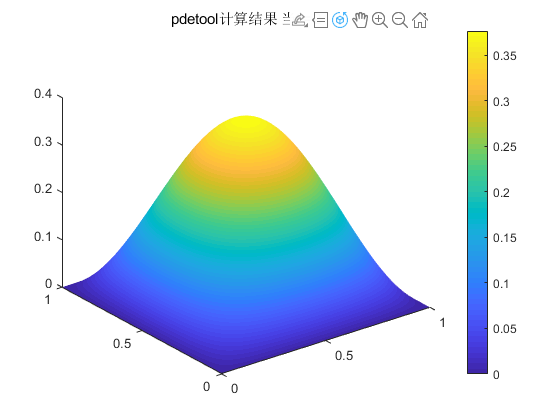

title(strcat('pdetool计算结果 当t = ', num2str(t)));
set(gcf,'Visible','on');   	    %强制图片弹出显示

**问题2：考虑如下的本征值问题。它大致相当于圆形波导中的TE模式，其中物理量u就是纵向磁场**$H_z$**。**


$$\begin{array}{l}
\Delta u+k_c^2 u=0\\
{\frac{\partial }{\partial r}u\left|\right.}_{r=a} =0
\end{array}$$


**        首先，利用分离变量法求解可得**


$$u=AJ_m \left(k_c r\right)\left\lbrace \textrm{cosm}\varphi \textrm{、sinm}\varphi \right\rbrace$$


**        考虑到边界条件有**


$$k_c =x_i^{\left(m\right)} /a$$


**        这就是上述本征值问题对应的本征函数和本征值。其中，**$x_i^{\left(m\right)}$**表示m阶贝塞尔函数的导数的第i个根。**

**        用以下的MATLAB代码可以求解**$H_{01}$**模式的本征值和本征模，并利用函数绘制模式分布。**

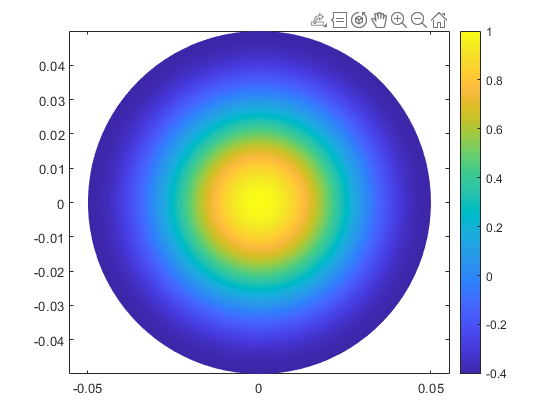

clear
clc
a=0.05;                             	%设置圆半径            
r=linspace(0,a,100);                     	%沿径向取100点
m=0;                                 	% 零阶模式
theta=linspace(0,2*pi,100);               	%沿角向取100点
[R,Theta]=meshgrid(r,theta);              	%绘制极坐标网格，并赋予R、Theta矩阵
kc01=fzero(@(x) besselj(1,x), 3)/a;         	%求一阶贝塞尔函数在3附近的根，得本征值
u=besselj(0,kc01*R).*cos(m*Theta);       	%计算场分布
X=R.*cos(Theta); Y=R.*sin(Theta);        	%转化为直角坐标系
figure(6)                                	%创建新窗口，绘制新的模式H01
pcolor(X,Y,u);                          	%绘制伪彩色图
shading interp;                         	%颜色做插值处理  
colorbar;                              	%绘制色阶图
axis equal;                             	%x、y方向等比例显示
set(gcf,'Visible','on');   	    %强制图片弹出显示

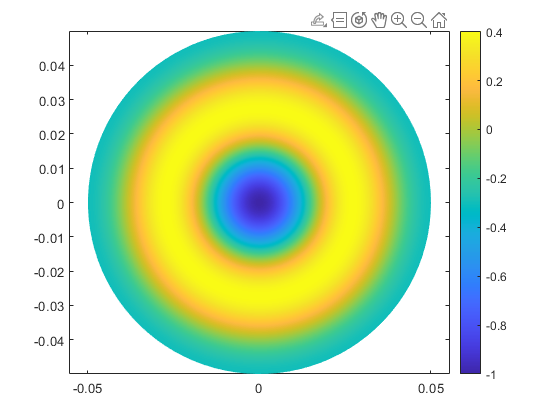

kc02=fzero(@(x) besselj(1,x), 6)/a;        	%求一阶贝塞尔函数在6附近的根，得本征值
u=besselj(0,kc02*R).*cos(m*Theta);       	%计算场分布
figure(7)                                	%创建新窗口，绘制新的模式H02
pcolor(X,Y,-u);	%绘制伪彩色图
shading interp;
colorbar;
axis equal;
set(gcf,'Visible','on');   	    %强制图片弹出显示

**        可以看出，由于**$m=0$**，所以模式分布具有轴对称的特点，与角向变量无关。查看结果可以知道**


$$\begin{array}{l}
k_c =76\ldotp 6341\left(H_{01} \right)\\
k_c =140\ldotp 3117\left(H_{02} \right)
\end{array}$$


进一步可求出波动问题的本征值：


$$\lambda \left(1\right)=k_c^2$$


lambda1H01 = kc01^2

lambda1H01 = 5.8728e+03

lambda1H02 = kc02^2

lambda1H02 = 1.9687e+04

**        可以利用PDETool工具箱进行上述问题的求解，当使用本征值的方程形式时，需要设置本征值的扫描区间。如求解H01模式，设置为[5000,6000]。**

              Basis= 10,  Time=   0.03,  New conv eig=  0
              Basis= 12,  Time=   0.08,  New conv eig=  0
              Basis= 14,  Time=   0.08,  New conv eig=  0
              Basis= 16,  Time=   0.08,  New conv eig=  0
              Basis= 18,  Time=   0.12,  New conv eig=  1
End of sweep: Basis= 18,  Time=   0.12,  New conv eig=  1
              Basis= 11,  Time=   0.12,  New conv eig=  0
              Basis= 13,  Time=   0.19,  New conv eig=  0
              Basis= 15,  Time=   0.19,  New conv eig=  0
End of sweep: Basis= 15,  Time=   0.19,  New conv eig=  0


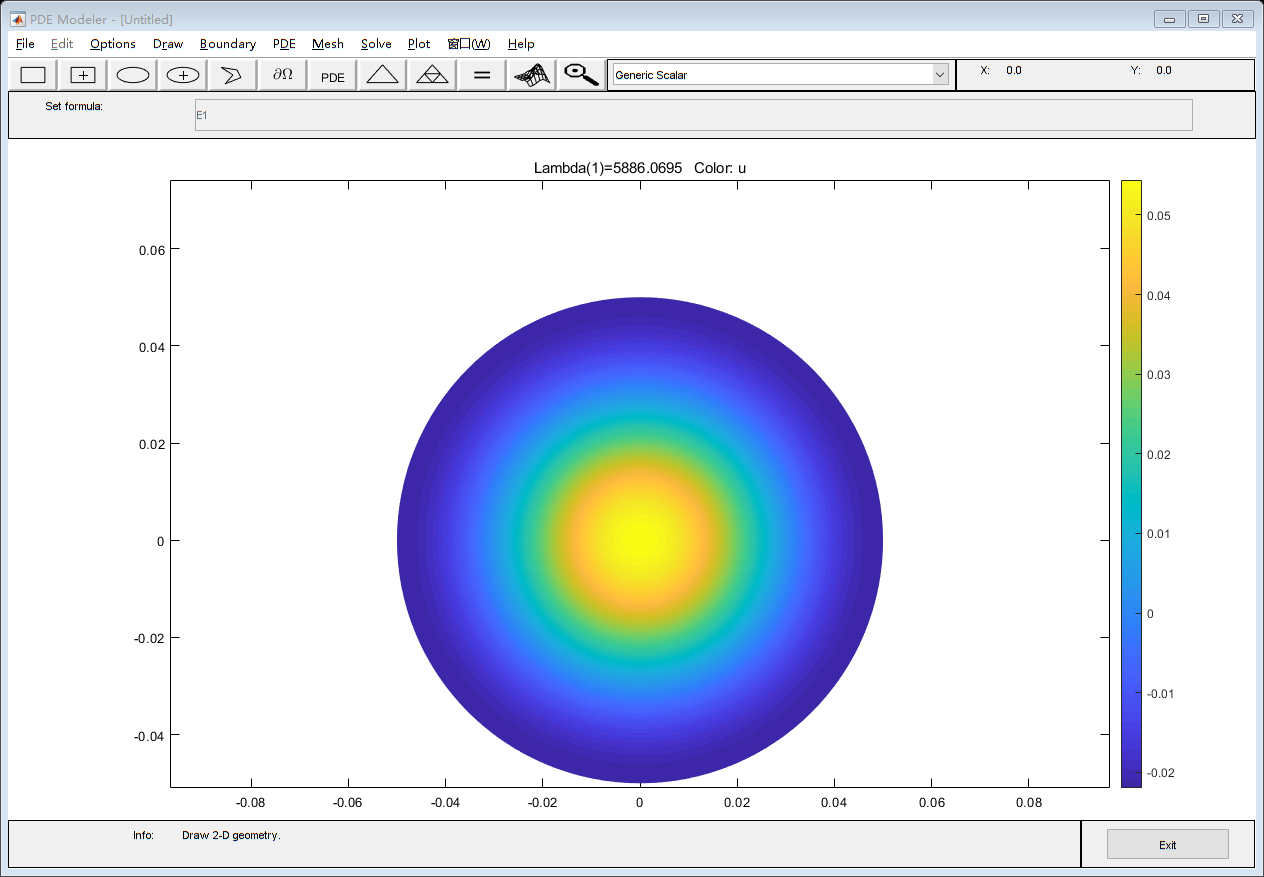

exit = false;  %是否运行后退出
range = '[5000 6000]'; %选择求解的模式
Eigenvalue(range,exit);

**    由于式中系数A的存在，因此，解析法和数值法得到的场值幅度不同，*****甚至正负恰好相反*****，但这并不影响它们对应于相同的模式。从结果可知，数值法对应的两个本征模为**


$$\begin{array}{l}
\lambda =5886\ldotp 0695\left(H_{01} \right)\\
\lambda =19815\ldotp 1006\left(H_{02} \right)
\end{array}$$


**    通过观察可以发现解析法和数值法对应的本征值几乎相同。**

**      *****此部分代码需要通过点击“运行节”运行，否则图片会输出混乱**

function pdemodel(t,exit)
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',1);
    set(ax,'DataAspectRatio',[1 1.5 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 3]);
    set(ax,'XLim',[0 1]);
    set(ax,'YLim',[0 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([0 1 1 0],'R1');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'dir',...
    1,...
    '1',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '0')
    pdesetbd(2,...
    'dir',...
    1,...
    '1',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(3,...
    '1.0',...
    '0.0',...
    '0',...
    '1.0',...
    ['0:',num2str(t)],...
    '0',...
    '3.*sin(pi*x).*sin(pi*y)',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['1.0';...
    '0.0';...
    '0  ';...
    '1.0'])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','7488','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 10 1 0 0 0 6 1 0 1 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve');
    if exit
       pdetool('exit');
    end
end
function Eigenvalue(range,exit)
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',1);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5468861454046632 1 16]);
    set(ax,'XLimMode','auto');
    set(ax,'YLim',[-0.050929172510518955 0.074070827489481045]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pdeellip(0,0,0.050000000000000003,0.050000000000000003,...
    0,'E1');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','E1')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'neu',...
    1,...
    '0',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(4,...
    '1.0',...
    '0.0',...
    '10.0',...
    '1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    range)
    setappdata(pde_fig,'currparam',...
    ['1.0 ';...
    '0.0 ';...
    '10.0';...
    '1.0 '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','6288','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 10 1 0 0 0 1 1 0 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
    if exit
       pdetool('exit');
    end
end